### Time and frequency signals

Record a time signal, inspect the spectrum and the spectogram

Recording starts!
End of Recording


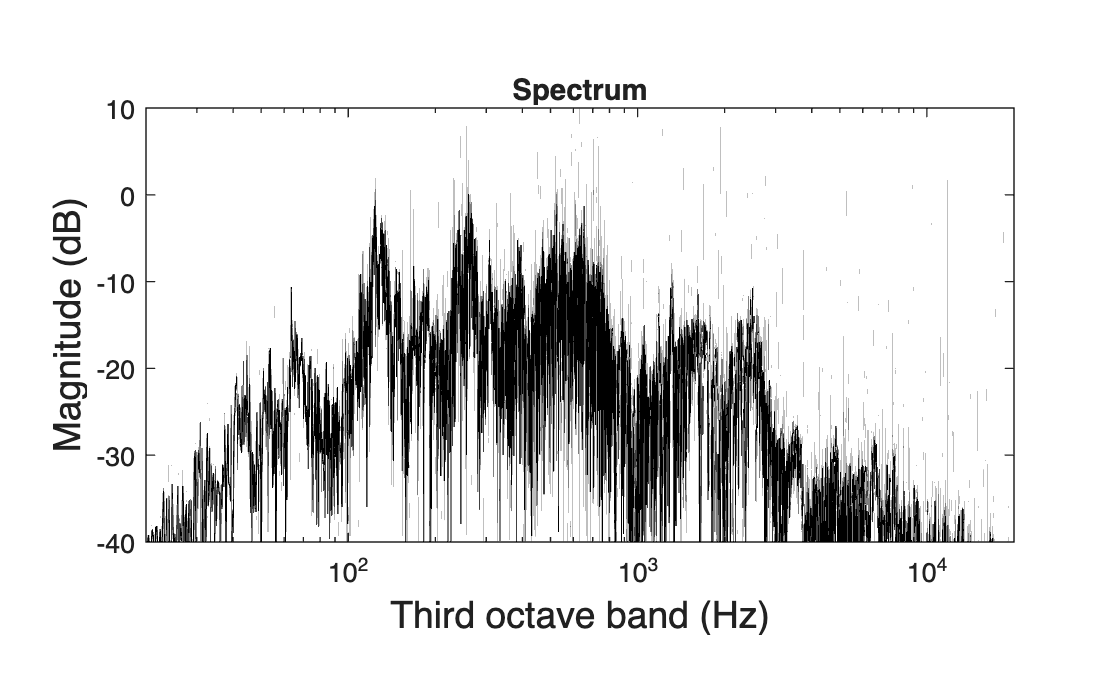

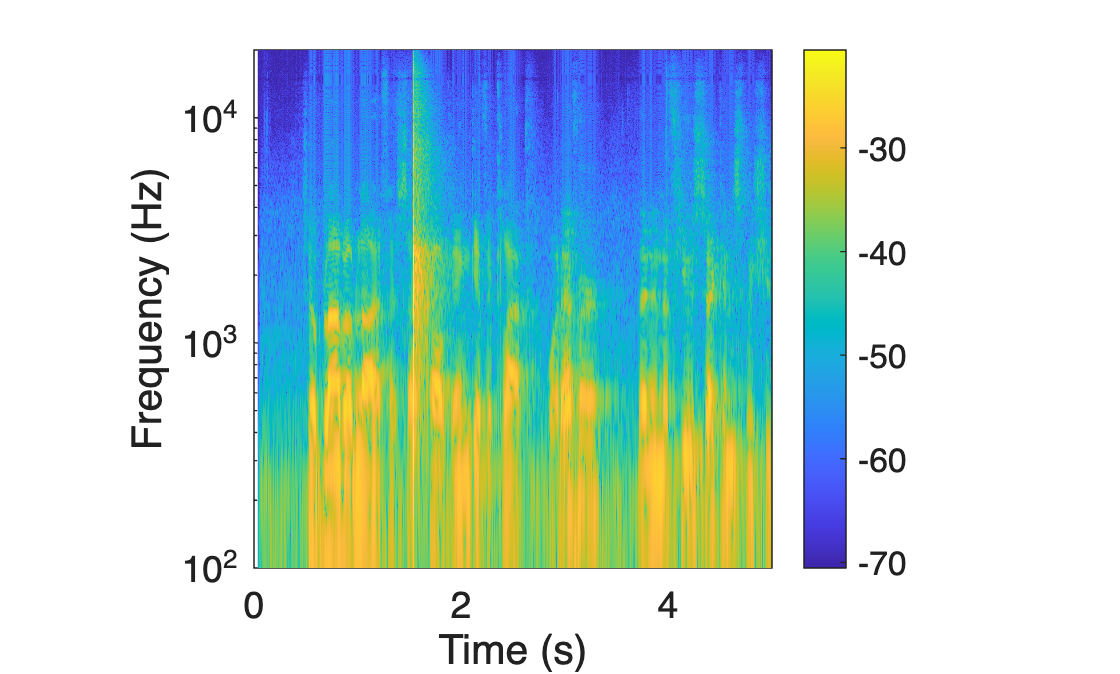

fs = 44100;         % sample frequency (Hz)
slength = 5;        % length of signal in seconds

audiorecordingEAA(fs,slength)

### Help functions

Feel free to modify to make it better!

function audiorecordingEAA(fs,slength)
close all
bits = 16;
recObj = audiorecorder(fs, bits, 1);

% Collect a sample of your speech with a microphone
disp('Recording starts!')
recordblocking(recObj, slength);
disp('End of Recording');

% Store data in double-precision array.
myRecording = getaudiodata(recObj);
y=myRecording;

dt = 1./fs;            % time step
Y = fft(y);            % spectrum  
Lp= 20.*log10(abs(Y)./max(abs(Y)));  % normalized magnitude
f = [0:fs*slength-1]./slength;  % frequency vector
df = 1./slength;                % frequency step

% plot the waveform
figure(30)
plot([1:fs*slength]./fs,y,'k-');
set(gca,'FontSize',10,'PlotBoxAspectRatio',[2 1 1],'Ylim',[-0.1 .1])
axis([0 slength -max(y).*1.5 max(y).*1.5])
xlabel('t (s)','FontSize',14)
ylabel('p (Pa)','FontSize',14)
title('waveform')
box on

% plot the spectrum
figure(31)
semilogx([0:fs*slength-1]./slength,Lp,'k');
set(gca,'FontSize',10,'PlotBoxAspectRatio',[2 1 1],'Ylim',[-20 0],'Xlim',[20 1e4])
axis([20 2e4 max(Lp)-40 max(Lp)+10])
xlabel('Third octave band (Hz)','FontSize',14)
ylabel('Magnitude (dB)','FontSize',14)
title('Spectrum')
box on

% plot the spectrogram
[S,F,T,P2] = spectrogram(y,fs/100,100,logspace(2,5,512*2),fs);

figure(32)
surf(T,F,10*log10((sqrt(abs(P2)))),'edgecolor','none'); axis tight;
view(0,90);
xlabel('Time (s)'); ylabel('Frequency (Hz)');
P2max =max (10*log10((sqrt(abs(P2(:))))));
caxis([P2max-50 P2max])
colorbar
shading interp
axis([0 slength 100 2e4])
set(gca,'YScale','log','FontSize',14,'PlotBoxAspectRatio',[1 1 1])
box on

end


